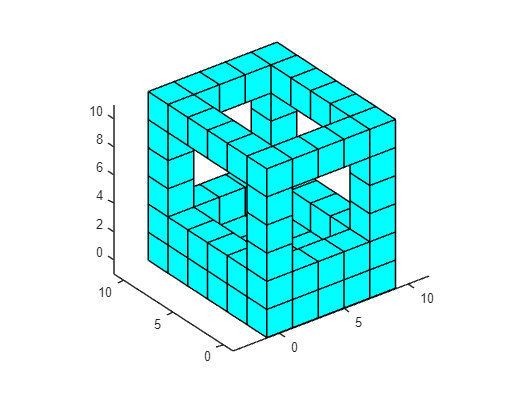

verticesCube = [
    -1, 1, 1, -1, -1, 1, 1, -1;
    -1, -1, 1, 1, -1, -1, 1, 1;
    -1, -1, -1, -1, 1, 1, 1, 1;
    1, 1, 1, 1, 1, 1, 1, 1
    ];

facesCube = [
    1, 2, 6, 5;
    2, 3, 7, 6;
    3, 4, 8, 7;
    4, 1, 5, 8;
    1, 2, 3, 4;
    5, 6, 7, 8
    ];


move1X = [
    1, 0, 0, 2;
    0, 1, 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];
move1Y = [
    1, 0, 0, 0;
    0, 1, 0, 2;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];
move1Z = [
    1, 0, 0, 0;
    0, 1, 0, 0;
    0, 0, 1, 2;
    0, 0, 0, 1
    ];

cube_1 = verticesCube;

for i = 1:5
    DrawShape(cube_1, facesCube, 'c');
    cube_2 = cube_1;
    for j = 1:5
        cube_2 = move1Y * cube_2;
        DrawShape(cube_2, facesCube, 'c');
        if (j == 5) || (i == 1) || (i == 5)
             cube_3 = cube_2;
             for k = 1:5
                cube_3 = move1Z * cube_3;
                if ((k == 5) || (k == 1) || (i == 5) || (i == 1)) && (j == 5) ||(k == 5) || (k == 1)
                    DrawShape(cube_3, facesCube, 'c');
                else
            %DrawEmpShape(cube_3);
            %DrawShape(cube_3, facesCube, 'w');
                end
             end
              cube_3 = move1Z * cube_2;
        DrawShape(cube_3, facesCube, 'c');
        end
    end
    cube_3 = cube_1;
    for k = 1:5
        cube_3 = move1Z * cube_3;
        if (i == 1) || (i == 5) ||(k == 5) || (k == 1)
            DrawShape(cube_3, facesCube, 'c');
        else
            %DrawEmpShape(cube_3);
            %DrawShape(cube_3, facesCube, 'w');
        end
    end
    cube_1 = move1X * cube_1;
end

%DrawShape (verticesCube, facesCube, 'c')
axis equal;
%view(90, 0);
view(3);

function DrawShape(vertices, faces, color)
    patch('Vertices', (vertices(1:3,:)./vertices(4,:))','Faces', faces, 'FaceColor', color);

end


